n1=[-7.21];
d1=[1 0.12 -2.368 ];
n2=-2750;
d2=[1 42.3 2750];
misstf=tf(n2,d2)


misstf =
 
         -2750
  -------------------
  s^2 + 42.3 s + 2750
 
Continuous-time transfer function.



servotf=tf(n1,d1);
ucsys=misstf*servotf


ucsys =
 
                   1.983e04
  -------------------------------------------
  s^4 + 42.42 s^3 + 2753 s^2 + 229.8 s - 6512
 
Continuous-time transfer function.



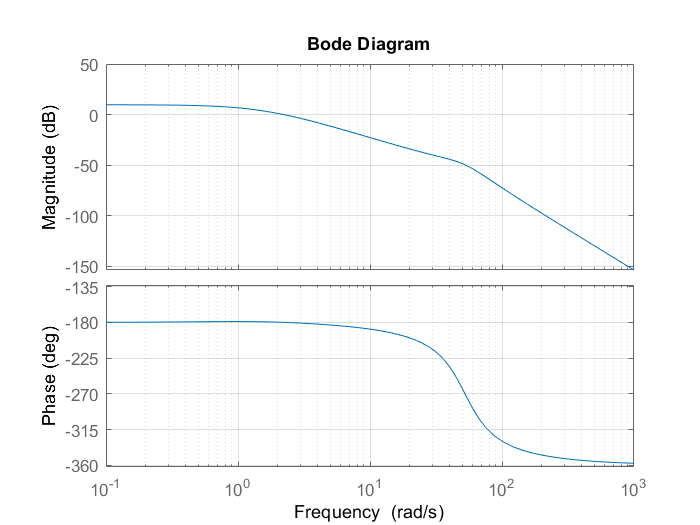

bode(ucsys)
grid on